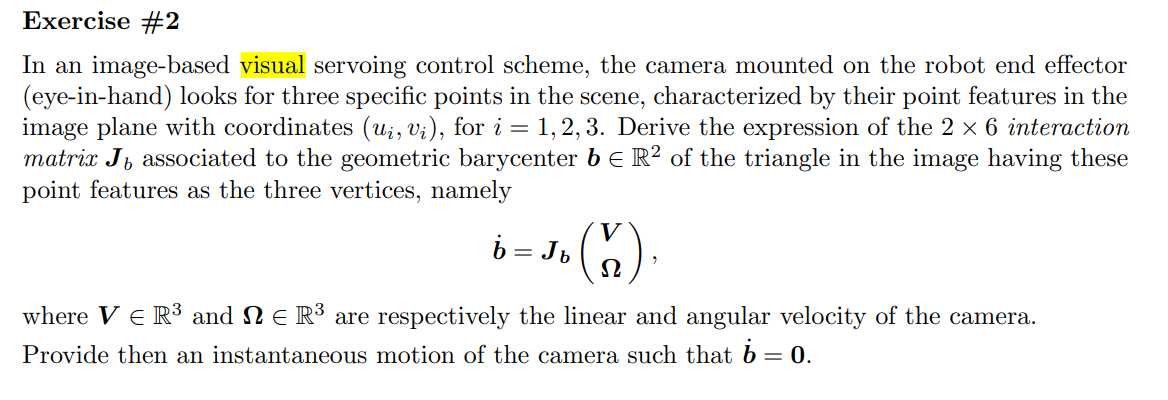

clc
clear all
close all

% addpath("Functions/Robotics1") % Linux
% addpath("Functions/Robotics2") % Linux
addpath("Functions\Robotics1") % Windows
addpath("Functions\Robotics2") % Windows


syms u1 u2 u3 v1 v2 v3 Z1 Z2 Z3 lambda real

J_p1 = interaction_matrix(u1, v1, Z1, lambda)

$$J\_p1 = \left(\begin{array}{cccccc} -\frac{\lambda }{Z_{1}} & 0 & \frac{u_{1}}{Z_{1}} & \frac{u_{1}\,v_{1}}{\lambda } & -\lambda -\frac{{u_{1}}^{2}}{\lambda } & v_{1}\\ 0 & -\frac{\lambda }{Z_{1}} & \frac{v_{1}}{Z_{1}} & \lambda +\frac{{v_{1}}^{2}}{\lambda } & -\frac{u_{1}\,v_{1}}{\lambda } & -u_{1} \end{array}\right)$$

J_p2 = interaction_matrix(u2, v2, Z2, lambda)

$$J\_p2 = \left(\begin{array}{cccccc} -\frac{\lambda }{Z_{2}} & 0 & \frac{u_{2}}{Z_{2}} & \frac{u_{2}\,v_{2}}{\lambda } & -\lambda -\frac{{u_{2}}^{2}}{\lambda } & v_{2}\\ 0 & -\frac{\lambda }{Z_{2}} & \frac{v_{2}}{Z_{2}} & \lambda +\frac{{v_{2}}^{2}}{\lambda } & -\frac{u_{2}\,v_{2}}{\lambda } & -u_{2} \end{array}\right)$$

J_p3 = interaction_matrix(u3, v3, Z3, lambda)

$$J\_p3 = \left(\begin{array}{cccccc} -\frac{\lambda }{Z_{3}} & 0 & \frac{u_{3}}{Z_{3}} & \frac{u_{3}\,v_{3}}{\lambda } & -\lambda -\frac{{u_{3}}^{2}}{\lambda } & v_{3}\\ 0 & -\frac{\lambda }{Z_{3}} & \frac{v_{3}}{Z_{3}} & \lambda +\frac{{v_{3}}^{2}}{\lambda } & -\frac{u_{3}\,v_{3}}{\lambda } & -u_{3} \end{array}\right)$$


b = 1/3*[u1 + u2 + u3; v1 + v2 + v3]

$$b = \left(\begin{array}{c} \frac{u_{1}}{3}+\frac{u_{2}}{3}+\frac{u_{3}}{3}\\ \frac{v_{1}}{3}+\frac{v_{2}}{3}+\frac{v_{3}}{3} \end{array}\right)$$


J_p_s = simplify(1/3 * (J_p1 + J_p2 + J_p3))

$$J\_p\_s = \begin{array}{l} \left(\begin{array}{cccccc} \sigma_{1} & 0 & \frac{u_{1}}{3\,Z_{1}}+\frac{u_{2}}{3\,Z_{2}}+\frac{u_{3}}{3\,Z_{3}} & \sigma_{2} & -\frac{3\,\lambda^{2}+{u_{1}}^{2}+{u_{2}}^{2}+{u_{3}}^{2}}{3\,\lambda } & \frac{v_{1}}{3}+\frac{v_{2}}{3}+\frac{v_{3}}{3}\\ 0 & \sigma_{1} & \frac{v_{1}}{3\,Z_{1}}+\frac{v_{2}}{3\,Z_{2}}+\frac{v_{3}}{3\,Z_{3}} & \frac{3\,\lambda^{2}+{v_{1}}^{2}+{v_{2}}^{2}+{v_{3}}^{2}}{3\,\lambda } & -\sigma_{2} & -\frac{u_{1}}{3}-\frac{u_{2}}{3}-\frac{u_{3}}{3} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=-\frac{\lambda }{3\,Z_{1}}-\frac{\lambda }{3\,Z_{2}}-\frac{\lambda }{3\,Z_{3}}\\ \sigma_{2}=\frac{u_{1}\,v_{1}+u_{2}\,v_{2}+u_{3}\,v_{3}}{3\,\lambda } \end{array}$$


n = simplify(null(J_p_s))

$$n = \begin{array}{l} \left(\begin{array}{cccc} \frac{Z_{1}\,Z_{2}\,u_{3}+Z_{1}\,Z_{3}\,u_{2}+Z_{2}\,Z_{3}\,u_{1}}{\lambda \,\sigma_{2}} & \sigma_{1} & -\frac{Z_{1}\,Z_{2}\,Z_{3}\,\left(3\,\lambda^{2}+{u_{1}}^{2}+{u_{2}}^{2}+{u_{3}}^{2}\right)}{\lambda^{2}\,\sigma_{2}} & \frac{Z_{1}\,Z_{2}\,Z_{3}\,\left(v_{1}+v_{2}+v_{3}\right)}{\lambda \,\sigma_{2}}\\ \frac{Z_{1}\,Z_{2}\,v_{3}+Z_{1}\,Z_{3}\,v_{2}+Z_{2}\,Z_{3}\,v_{1}}{\lambda \,\sigma_{2}} & \frac{Z_{1}\,Z_{2}\,Z_{3}\,\left(3\,\lambda^{2}+{v_{1}}^{2}+{v_{2}}^{2}+{v_{3}}^{2}\right)}{\lambda^{2}\,\sigma_{2}} & -\sigma_{1} & -\frac{Z_{1}\,Z_{2}\,Z_{3}\,\left(u_{1}+u_{2}+u_{3}\right)}{\lambda \,\sigma_{2}}\\ 1 & 0 & 0 & 0\\ 0 & 1 & 0 & 0\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{Z_{1}\,Z_{2}\,Z_{3}\,\left(u_{1}\,v_{1}+u_{2}\,v_{2}+u_{3}\,v_{3}\right)}{\lambda^{2}\,\sigma_{2}}\\ \sigma_{2}=Z_{1}\,Z_{2}+Z_{1}\,Z_{3}+Z_{2}\,Z_{3} \end{array}$$


simplify(J_p_s * n(:, 1))

$$ans = \left(\begin{array}{c} 0\\ 0 \end{array}\right)$$